# UNSUPERVISED LEARNING

1.  load the iris data set with the command `load 'fisheriris'`.  Two data structures will appear in your workspace: `meas` and `species`.  The data structure `meas` contains the flower measurements as a 150x4 matrix -- 150 samples, each with 4 variables.  The data structure `species` has text labels for each iris type; these labels are not needed for the clustering exercises here.  

load fisheriris
meas

meas =           5.1          3.5          1.4          0.2
          4.9            3          1.4          0.2
          4.7          3.2          1.3          0.2
          4.6          3.1          1.5          0.2
            5          3.6          1.4          0.2
          5.4          3.9          1.7          0.4
          4.6          3.4          1.4          0.3
            5          3.4          1.5          0.2
          4.4          2.9          1.4          0.2
          4.9          3.1          1.5          0.1


2.  Cluster the iris data set using `kmeans` and create a dendrogram using using matlab's `linkage.m`. Compare the results.

[idx, C] = kmeans(meas,3)

idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


C =         5.006        3.428        1.462        0.246
       6.8538       3.0769       5.7154       2.0538
       5.8836        2.741       4.3885       1.4344


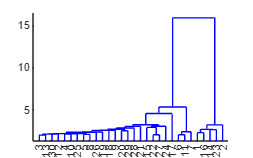


d = pdist(meas);
m = squareform(d);
ml = linkage(m);
dendrogram(ml)

3.  Run `origbcm.m` on a dataset of 8 normalized random vectors.  Comment on the result.

rs = 0;
p8data = .7*ones(8)+.3*eye(8);
p8data = normc(p8data);
p8data'*p8data

ans =             1      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968            1      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968            1      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968            1      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968            1      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968            1      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968            1      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968            1


b0 = initorigbcm(8,2,rs)

b0 = struct with fields:
    wts: [0.62945 0.81158 -0.74603 0.82675 0.26472 -0.80492 -0.443 0.093763]
     rb: 0

bf = origbcm(b0,p8data,100000,.005,rs)

bf = struct with fields:
    wts: [2.2045 3.2723 -2.2539 3.2704 0.57052 -2.3536 -1.5646 -0.062638]
     rb: 1.0817

bf.wts*p8data

ans =        1.3395       1.4917      0.70406       1.4915       1.1066      0.68986      0.80232       1.0164


#  LANGUAGE

Create an SRN model of the grammar below.  Generate a list of training strings. 

Test the model on grammatical strings, such as BPXXRJXXXRQE

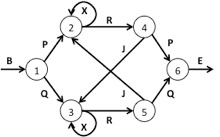

% setup list generation
reber.labels = 'BPQXRJE'

reber = struct with fields:
    labels: 'BPQXRJE'
       ind: [8×8 double]
      prob: [8×8 double]

reber.ind = [ % col->row weight
    0 1 0 0 0 0 0 0;
    0 0 2 3 0 0 0 0;
    0 0 4 0 5 0 0 0;
    0 0 0 4 0 5 0 0;
    0 0 0 6 0 0 2 0;
    0 0 6 0 0 0 3 0;
    0 0 0 0 0 0 0 7;
    0 0 0 0 0 0 0 0;]

reber = struct with fields:
    labels: 'BPQXRJE'
       ind: [8×8 double]
      prob: [8×8 double]

reber.prob = [ % 0.5 for two output, 1 for one output
    0    1.0  0    0    0    0    0    0;
    0    0    0.5  0.5  0    0    0    0;
    0    0    0.5  0    0.5  0    0    0;
    0    0    0    0.5  0    0.5  0    0;
    0    0    0    0.5  0    0    0.5  0;
    0    0    0.5  0    0    0    0.5  0;
    0    0    0    0    0    0    0    1;
    0    0    0    0    0    0    0    0;]

reber = struct with fields:
    labels: 'BPQXRJE'
       ind: [8×8 double]
      prob: [8×8 double]


% make training list
list = makestringlist(reber,1000)

list = struct with fields:
      list: [1 3 4 5 3 7 8 1 2 5 6 5 6 5 6 5 3 7 8 1 3 4 4 4 5 6 5 6 5 6 4 4 5 6 4 5 3 7 8 1 2 5 2 7 8 1 2 4 5 2 7 8 1 3 4 4 4 4 5 6 5 6 5 6 5 2 7 8 1 2 4 5 6 5 3 7 8 1 2 4 5 6 5 3 7 8 1 2 4 5 6 5 6 4 4 4 5 2 7 8 1 3 5 6 5 6 4 4 4 4 4 4 4 5 3 7 8 1 2 … ]
    states: [1 2 4 4 6 7 1 2 3 5 4 6 3 5 4 6 7 1 2 4 4 4 4 6 3 5 4 6 3 3 3 5 4 4 6 7 1 2 3 5 7 1 2 3 3 5 7 1 2 4 4 4 4 4 6 3 5 4 6 3 5 7 1 2 3 3 5 4 6 7 1 2 3 3 5 4 6 7 1 2 3 3 5 4 6 3 3 3 3 5 7 1 2 4 6 3 5 4 4 4 4 4 4 4 4 6 7 1 2 3 5 4 4 6 3 3 3 3 3 … ]
       ind: [1 8 20 40 46 53 69 78 87 101 118 133 144 156 166 173 179 197 206 219 226 232 239 252 261 267 278 289 295 307 314 327 334 340 351 360 376 383 398 405 411 426 435 441 475 481 493 499 505 511 517 530 540 546 562 577 587 593 600 615 621 627 … ]

% init net
n0=initnet3srnx(5,3,5,1,3,rs)

n0 = struct with fields:
        wih: [3×5 double]
         hh: [3×3 double]
      hbias: [0.17874 0.25774 0.24313]
      whout: [5×3 double]
      obias: [0.79655 0.8856 -0.93938 -0.030707 -0.16324]
    context: [0 0 0]

% train net
nf=bp3srn(n0,list,30000,.02,0)

Unrecognized function or variable 'hidlayersrn'.
Error in Assignment8>forw1p3srn (line 129)
netact.hid=hidlayersrn(p,netwk.context,netwk.wih,netwk.hh,netwk.hbias,nois);
Error in Assignment8>cyc3srn (line 135)
activity=forw1p3srn(nstruct,pin,noi) ;
Error in 

% FIXME hidlayersrn() not provided
% BPXXRJXXXRQE = 124456444537
stringprocv4X(nf,[1 2 4 4 5 6 4 4 4 5 3 7],reber)

## Attachments

function babynet = initorigbcm( nin,range,rs )
%initialize bcm cell
rng(rs);
babynet.wts=range*(rand(1,nin)-0.5) ;
babynet.rb = 0 ;
end

function finalcell = origbcm( initcell, pset, niter, dt, rs )
%iterates iterbcm
cell=initcell;
avgpat=sum(pset,2)/size(pset,2);
rng(rs) ;
for i=1:niter
    apat = pset(:,irand(size(pset,2),1)) ;
    r=cell.wts*apat ;
    cell.rb = cell.wts*avgpat ;
    cell.wts = cell.wts + dt*r*(r-cell.rb*cell.rb)*apat' ;
end
finalcell=cell;
end




function netstruct=initnet3srnx(n1,n2,n3,uamp,vamp,rs)
rng(rs);
netstruct.wih=uamp*(rand(n2,n1)-0.5) ;
netstruct.hh=uamp*(rand(n2,n2)-0.5) ;
netstruct.hbias=uamp*(rand(1,n2)-0.5) ;
netstruct.whout=vamp*(rand(n3,n2)-0.5) ;
netstruct.obias=vamp*(rand(1,n3)-0.5);
netstruct.context=zeros(1,n2);
end

function strings = makestringlist(tgram,nstrings)
jj=1; % initial state
strings.list=[];
strings.states=[];
nstates=size(tgram.prob,2);
for ii=1:nstrings
    strings.ind(ii)=jj ; %index into superstring
    seq=[]; %initialize one string
    st=1;
    stlist=[] ; %initial state list
    while (st<nstates)
        rr=rand();
        cumu=0; i=0;
        while (cumu<rr)
            i=i+1;
            cumu=cumu+tgram.prob(st,i);
        end
        letter=tgram.ind(st,i) ;
        seq=[seq letter];
        stlist=[stlist st];
        st=i;
    end
    seq=[seq nstates] ; % append end character to seq
    strings.list=[strings.list seq];
    jj=jj+size(seq,2);
    strings.states=[strings.states stlist];
end
end


function finalnet=bp3srn(net0,strlist,niter,eta,nlev)
netk=net0;
for i=1:niter
    ts=selectstring(strlist) ; % new training string               
    netk.context=zeros(size(netk.wih,1),1); % resets context 
    for j=1:size(ts,2)-1 % this loop trains a single string
        netk=cyc3srn(netk,ts(j),ts(j+1),eta,nlev) ;
    end
end
finalnet=netk;
end


function sg = selectstring(sdata)
j=randi(size(sdata.ind,2)) ;
if (j<size(sdata.ind,2)) sg=sdata.list(sdata.ind(j):sdata.ind(j+1)-1);
else sg=sdata.list(sdata.ind(j):size(sdata.list,2)) ;
end
end

function netact=forw1p3srn(netwk,p,nois)
netact.hid=hidlayersrn(p,netwk.context,netwk.wih,netwk.hh,netwk.hbias,nois);
netact.out=layersig01(netact.hid,netwk.whout,netwk.obias) ;
end

function newstruct=cyc3srn(nstruct,pin,pout,dt,noi)
newstruct=nstruct;
activity=forw1p3srn(nstruct,pin,noi) ;
tvec=zeros(size(nstruct.obias)) ;
tvec(pout)=1;
odelt=tvec-activity.out; %output deltas
hdelt=0.5*(nstruct.whout'*odelt').*(1+activity.hid').*(1-activity.hid');%hid deltas
%adjust weights and biases
newstruct.whout=newstruct.whout+dt*odelt'*activity.hid ;
newstruct.obias=newstruct.obias+dt*odelt ;
newstruct.wih(:,pin)=newstruct.wih(:,pin)+dt*hdelt; %just update weights from active input
newstruct.hbias=newstruct.hbias+dt*hdelt' ;
newstruct.hh=newstruct.hh+dt*hdelt*nstruct.context ;
newstruct.context=activity.hid ;
end

function [sout,hlist,slist] = stringprocv4X(netwk,strg,gramm)
hlist=[] ;
ctxinp=zeros(1,size(netwk.wih,1));
slist=[] ;
lets=gramm.labels(strg)

%STRINGS!!!
s1=[] ;
sout=[];

for j=1:size(strg,2)-1
    hhh=hidlayersrn(strg(j),ctxinp,netwk.wih,netwk.hh,netwk.hbias,0.0);
    ou=layersig01(hhh,netwk.whout,netwk.obias);
    hlist=[hlist;hhh] ;
    s1=[s1,lets(j)];
    scell=cellstr(s1) ;
    slist=[slist;scell] ;
    sout=[sout, sprintf('%c %c',gramm.labels(strg(j)), gramm.labels(strg(j+1)))] ;
    for kk=1:size(netwk.whout,1)
        sout=[sout sprintf('%6.3f',ou(kk))];
        end
    sout=[sout, sprintf('\n')];

    ctxinp=hhh;
end
end
